# Lab 1: Nutrition Lab

Brian Kim

## Background

## Data Description

The dataset under scrutiny is derived from the National Health and Nutrition Examination Survey (NHANES) which is important for understanding the health and nutritional disposition of US citizens. The 

## Exploratory Analysis

% Read in dataset
data = readtable('C:\BrianKim\Code\biostat521\Lab 1\NUTR_521_lab_data.xlsx');

% Organize Data into variables
albumin = data.URXUMS;
HEI = data.HEI2015_TOTAL_SCORE;
gender = data.RIAGENDR;
age = data.RIDAGEYR;
race = data.RIDRETH3;
education = data.DMDEDUC2;
bmi = data.BMXBMI;
systolic = data.BPXSY1;
alc = data.WkAlcDays;

### ## Albumin Levels

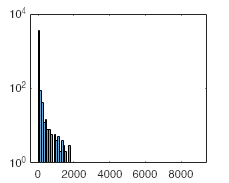

histogram(albumin);
set(gca,'YScale','log');

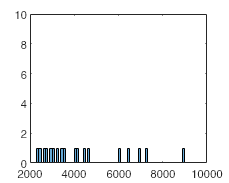


% Check for values above 2000
histogram(albumin);
xlim([2000 10000]);
ylim([0 10]);

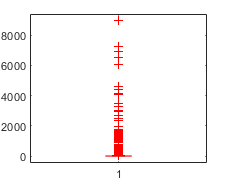


% Box plot
boxplot(albumin);

### HEI 2015

HEI data is not normally distributed. 

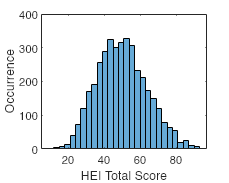

% Univariate Data Visualization
histogram(HEI);
xlabel('HEI Total Score')
ylabel('Occurrence')

% Basic Statistics
HEI_mean = mean(HEI)

HEI_mean = 50.1274

HEI_median = median(HEI)

HEI_median = 49.4008

HEI_sd = std(HEI)

HEI_sd = 13.8621

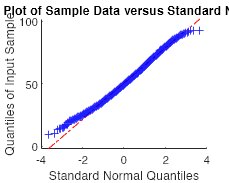


% Checks for Normality
qqplot(HEI) % If data is normally distributed, the points will lie roughly on the 45-degree reference line shown in red.

% Lilliefors Test
[hypothesis, pval, kstat, cv] = lillietest(HEI);

if hypothesis == 0
    disp('Data seems to be normally distributed');
else
    disp('Data does not seem to be normally distributed');
end

Data does not seem to be normally distributed



% Kolmogorov-Smirnov Test
[hypothesis, pval] = kstest((HEI - mean(HEI)) / std(HEI));
if hypothesis == 0
    disp('Data seems to be normally distributed');
else
    disp('Data does not seem to be normally distributed');
end

Data does not seem to be normally distributed


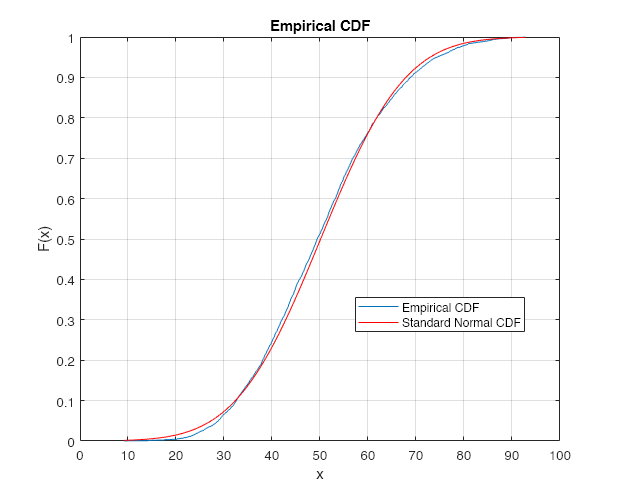


% Plot Cumulative Distribution Plot
cdfplot(HEI);
hold on;
x_values = linspace(min(HEI),max(HEI));
plot(x_values, normcdf(x_values, HEI_mean, HEI_sd),'r-');
legend('Empirical CDF','Standard Normal CDF','Location','best')
hold off;

### Gender

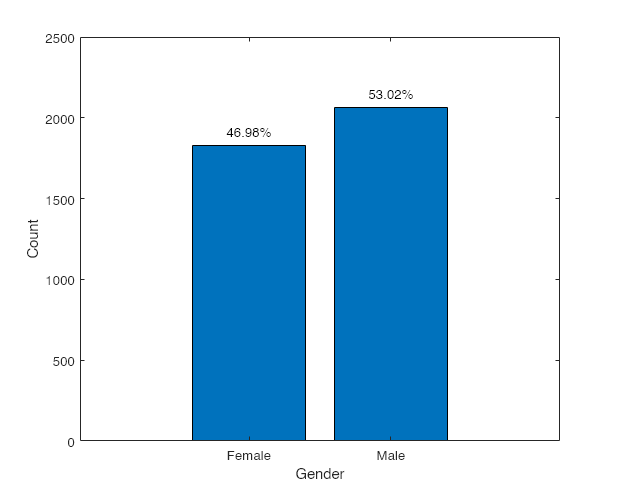

[gc gr] = groupcounts(gender);
figure;
bar(gc);
set(gca, 'xticklabel',gr);
xlabel('Gender');
ylabel('Count');
gender_percentages = (gc / sum(gc)) * 100;
for i = 1:length(gc)
    str = sprintf('%.2f%%', gender_percentages(i)); % Format the percentage with two decimal places
    text(i, gc(i) + max(gc)*0.02, str, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

### Age

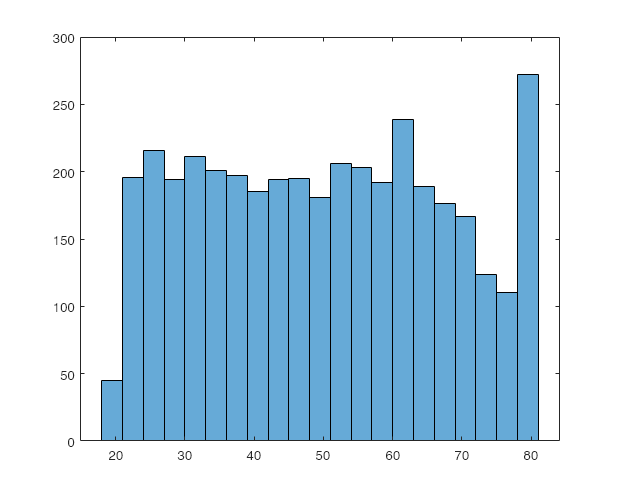

histogram(age);

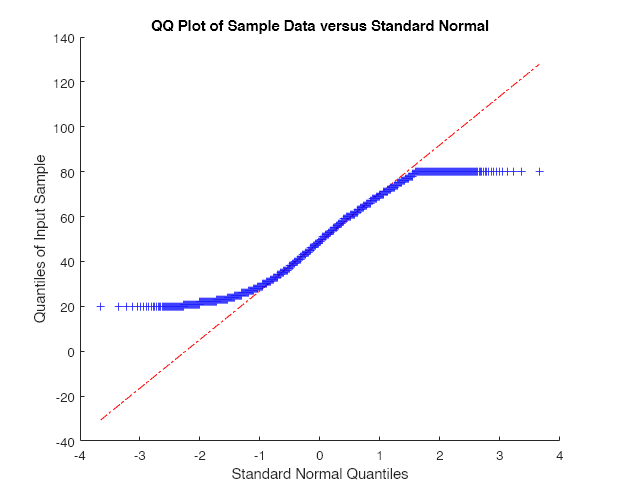


% Check for uniformity
qqplot(age);


% Kolmogorov-Smirnov Test
[hypothesis, pval] = kstest((age-min(age))/ (max(age)-min(age)));
if hypothesis == 0
    disp('Data seems to be uniformly distributed');
else
    disp('Data does not seem to be uniformly distributed');
end

Data does not seem to be uniformly distributed


### Race

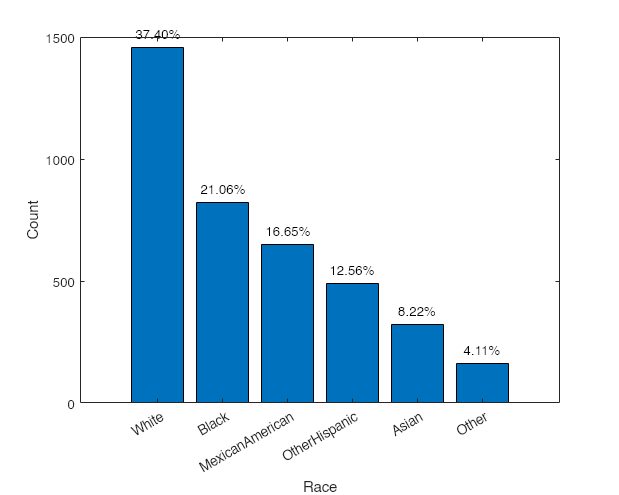

[gc gr] = groupcounts(race);

[sorted_gc, sorted_idx] = sort(gc, 'descend');
sorted_gr = gr(sorted_idx);

bar(sorted_gc);
xlabel('Race');
ylabel('Count');
set(gca, 'xticklabel',sorted_gr);
race_percentages = (sorted_gc / sum(sorted_gc)) * 100;
for i = 1:length(sorted_gc)
    str = sprintf('%.2f%%', race_percentages(i)); % Format the percentage with two decimal places
    text(i, sorted_gc(i) + max(sorted_gc)*0.02, str, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

### Education Level

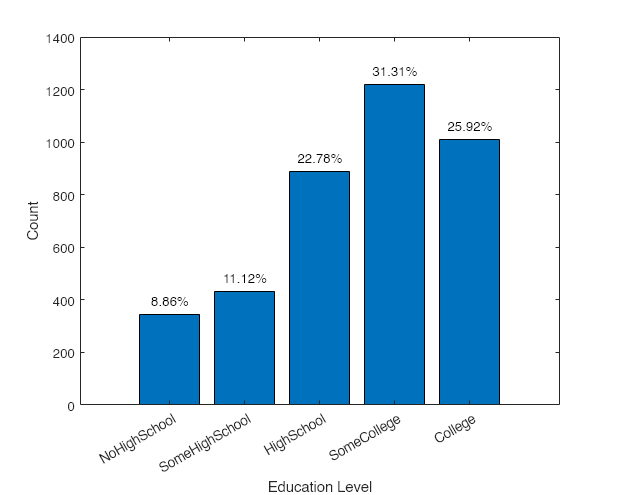

[gc gr] = groupcounts(education);

% Custom Order
custom_order = [3, 5, 2, 4, 1];
% Reorder based on the custom order
custom_gc = gc(custom_order);
custom_gr = gr(custom_order);

% Create the bar plot with reordered data
bar(custom_gc);
set(gca, 'xticklabel', custom_gr);
xlabel('Education Level');
ylabel('Count');

% Calculate the percentages for the reordered data
edu_percentages = (custom_gc / sum(custom_gc)) * 100;

% Annotate the percentages above the bars
for i = 1:length(custom_gc)
    str = sprintf('%.2f%%', edu_percentages(i)); % Format the percentage with two decimal places
    text(i, custom_gc(i) + max(custom_gc)*0.02, str, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

### BMI

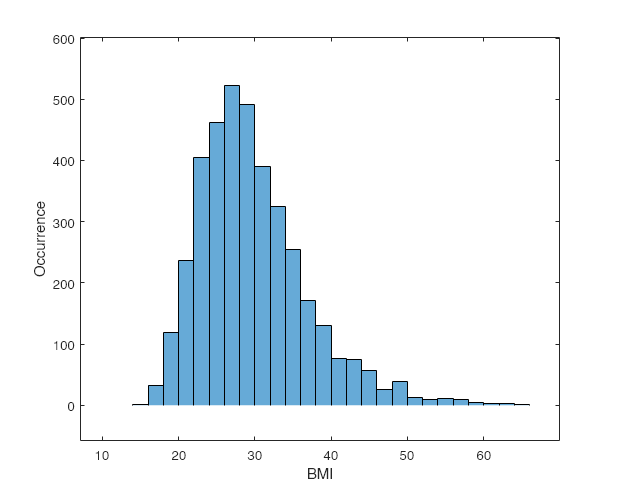

histogram(bmi);
xlabel('BMI')
ylabel('Occurrence');


bmi_mean = nanmean(bmi)

bmi_mean = 29.7286

bmi_median = nanmedian(bmi)

bmi_median = 28.6000

bmi_sd = nanstd(bmi)

bmi_sd = 7.0996

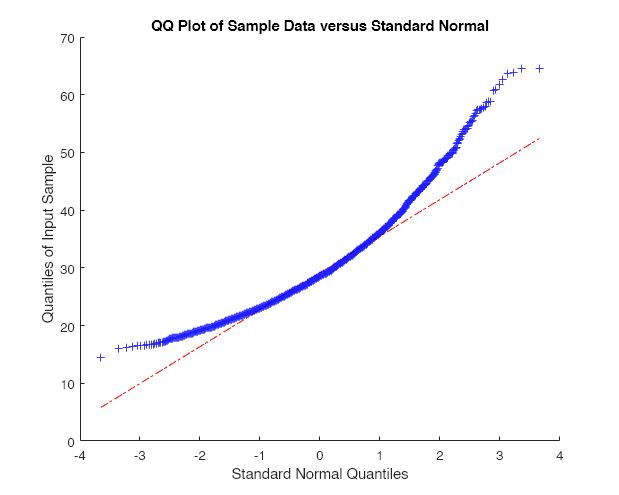


qqplot(bmi);


% Check Skew
skew_val = skewness(bmi);
disp(['The skewness of the data is: ', num2str(skew_val)]);

The skewness of the data is: 1.0926


### Systolic Blood Pressure

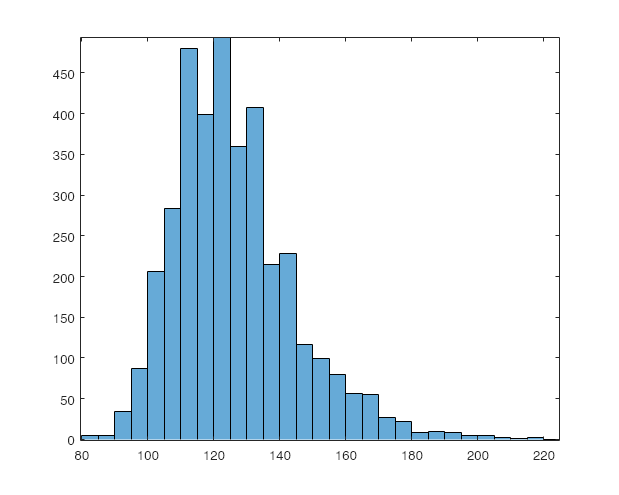

histogram(systolic);

### Diabetes

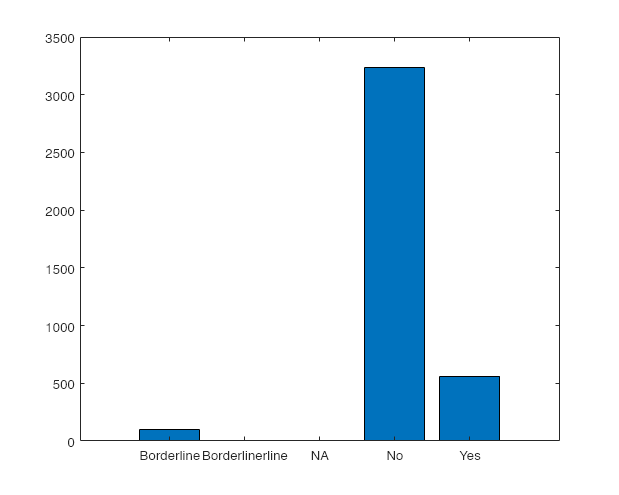

diabetes = data.DIQ010;
[gc gr] = groupcounts(diabetes);
bar(gc);
set(gca, 'xticklabel', gr);

### Number of Alcoholic Drinks / Week

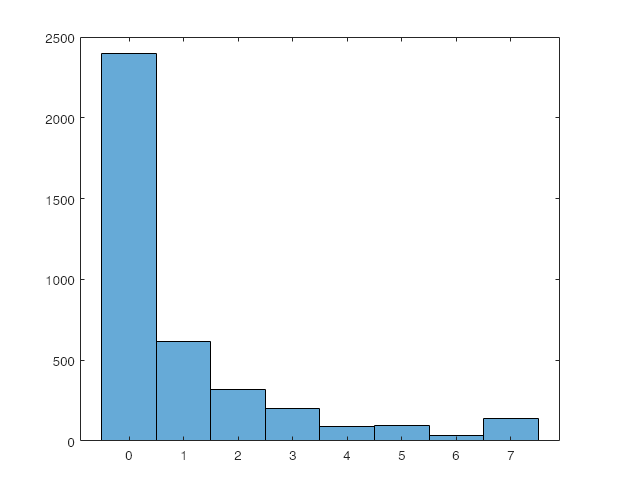

histogram(alc);

## Simple Bivariate Analysis

% HEI x BMI
scatter(HEI, bmi);
scatter(HEI, albumin);



scatter(bmi, albumin);
ylim([0 100]);
% HEI x Age
scatter(age, HEI);

scatter(age, albumin);
ylim([0 100])

scatter(, albumin);

% Alc x bmi
scatter(alc, bmi);

## Multivariate Analysis

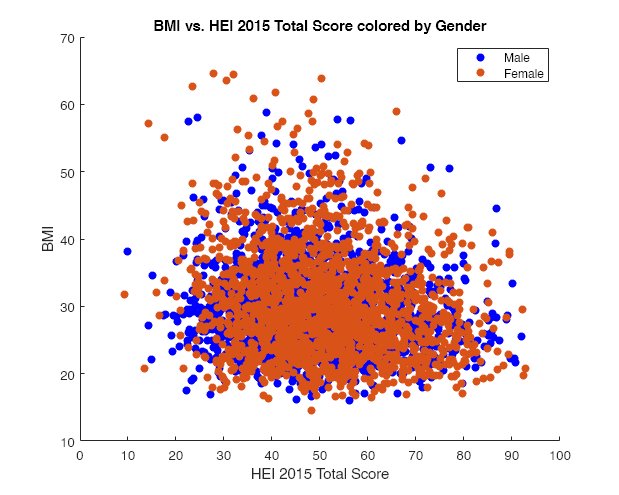

% HEI x BMI x Gender
male_indices = find(strcmp(gender, 'Male'));
female_indices = find(strcmp(gender, 'Female'));
figure;
scatter(HEI(male_indices), bmi(male_indices), 'b', 'filled'); % Blue for males
hold on;
scatter(HEI(female_indices), bmi(female_indices), 'o', 'filled'); % Red for females
xlabel('HEI 2015 Total Score');
ylabel('BMI');
legend('Male', 'Female');
title('BMI vs. HEI 2015 Total Score colored by Gender');


% HEI x Age x BMI
